# SISTEMES d'EQUACIONS (SESSIÓ 8)

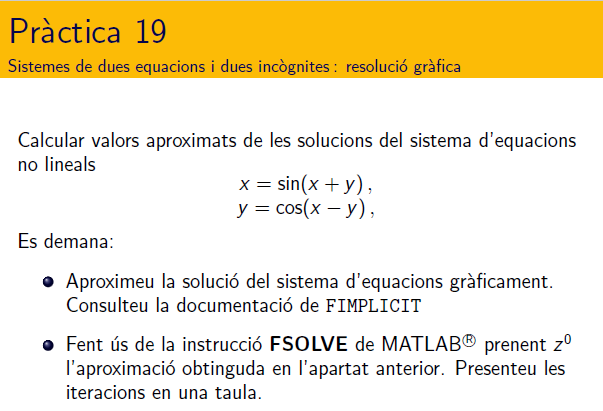

#### Resolució.

- Representeu en un mateix gràfic, les corbes $x-\sin(x+y)=0$ i $y-\cos(x-y)=0$ per a $x\in[-5,5]$ i per a $y\in[-5,5]$

F1=@(x,y)x-sin(x+y);
F2=@(x,y)y-cos(x-y);
% fimplicit({F1,F2})              

-  Canvieu el domini de les variables x i y a l'entorn del punt on es creuen les dues gràfiques

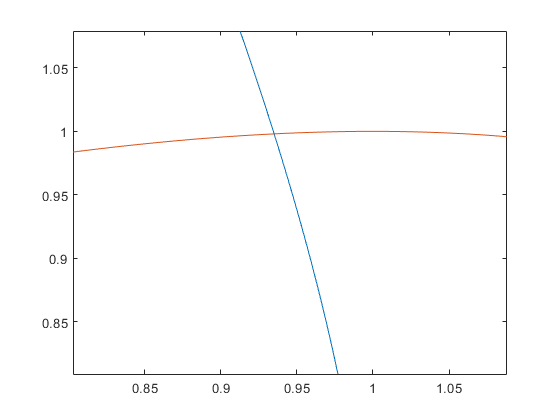

fimplicit({F1,F2},[ 0, 2 ,0 , 2])   

xlim([0.803 1.088])
ylim([0.809 1.079])

-  Calcular el punt on es creuen les dues gràfiques amb **FSOLVE** de Matlab. Per això cal definir el sistema d'equacions en una funció. (vegeu al final del document)

% doc fsolve
 clearvars;
 F = system([1,1]); disp(F')   % Valor de la funció que defineix el sistema d'equacions en [1;1]

    0.0907
         0



sol= fsolve(@system,[1,1])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


sol =     0.9351    0.9980


 options = optimoptions('fsolve','Display','iter');
 z0 = [1;1]; 
 [x,fval] = fsolve(@system,z0,options)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00822696                         0.128               1
     1          6     7.74869e-06      0.0640488        0.00285               1
     2          9      1.4696e-11     0.00216057       5.09e-06               1
     3         12     3.04197e-23    2.70288e-06       6.97e-12               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x =     0.9351
    0.9980


fval = 	1.0e+-11 *

    0.5227    0.1759


function F=system(z)
    F(1) = z(1)-sin(z(1)+z(2));
    F(2) = z(2)-cos(z(1)-z(2));
end